clear; clc;

%reference phantom image 
N = 128;
% phantom_img = phantom('Modified Shepp-Logan',N);
phantom_img = phantom('Modified Shepp-Logan',N);

%generating simulated projection data -- sinogram
theta = 0:179; %projection angles
[sinogram,xp] = radon(phantom_img,theta);

%MLEM variables
num_iters=30; %iterations
mlem_recon=ones(N,N); %for reconstructed image
ones_img=ones(N,N); %to calculate the normalization factor

%normalization factor (backprojection of a sinogram of all ones) -- sensitivity matrix components \sum_i a_{ij}
sens_matrix = iradon(radon(ones_img, theta), theta, 'linear', 'none', 1, N);
sens_matrix(sens_matrix <= 0) = 1e-6; %in case there are any zero

%iteration Loop
for iter = 1:num_iters
    %forward proj of the current estimate
    fp = radon(mlem_recon,theta);
    
    %ratio of measured sinogram/expected sinogram
    ratio = sinogram ./ (fp+1e-6); 
    
    %back-projection of the ratio
    bp_ratio = iradon(ratio,theta,'linear','none',1,N);
    
    %update the image estimate
    mlem_recon = (mlem_recon./sens_matrix) .* bp_ratio;
    
    %if there are any - values
    mlem_recon(mlem_recon<0) = 0;
    
    %progress
    fprintf('Iteration %d/%d completed.\n', iter, num_iters);
end

Iteration 1/30 completed.
Iteration 2/30 completed.
Iteration 3/30 completed.
Iteration 4/30 completed.
Iteration 5/30 completed.
Iteration 6/30 completed.
Iteration 7/30 completed.
Iteration 8/30 completed.
Iteration 9/30 completed.
Iteration 10/30 completed.
Iteration 11/30 completed.
Iteration 12/30 completed.
Iteration 13/30 completed.
Iteration 14/30 completed.
Iteration 15/30 completed.
Iteration 16/30 completed.
Iteration 17/30 completed.
Iteration 18/30 completed.
Iteration 19/30 completed.
Iteration 20/30 completed.
Iteration 21/30 completed.
Iteration 22/30 completed.
Iteration 23/30 completed.
Iteration 24/30 completed.
Iteration 25/30 completed.
Iteration 26/30 completed.
Iteration 27/30 completed.
Iteration 28/30 completed.
Iteration 29/30 completed.
Iteration 30/30 completed.


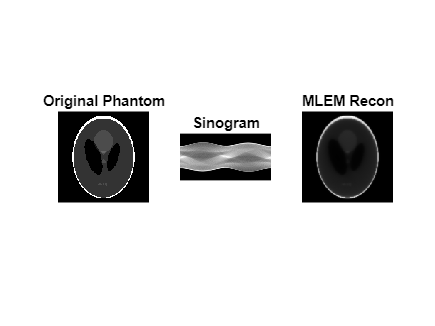


%results
figure;
subplot(1,3,1); imshow(phantom_img, []); title('Original Phantom');
subplot(1,3,2); imshow(sinogram, []); title('Sinogram');
subplot(1,3,3); imshow(mlem_recon, []); title('MLEM Recon');